# Cleaning Workspace

clear;
close all;
clc;

# Initialization Parameters

## Ploting Parameters

linewidth  = 2;
fontname   = 'Times New Roman';
fontsize   = 20;
markersize = 10;

## FFT Ploting Parameters

N_FFT  = 1024;
freq = 2*pi*linspace(-0.5,0.5,N_FFT);

## Data Transmission Parameters

Parameters related to the data transmission, e.g., number of bits, constellation size, number of subcarriers, and number of transmitted blocks.

B     = 2;                             % Number of bits in a symbol
Q     = 2^B;                           % Constellation size
N     = 10;                            % Number of symbols per data block
N_BLK = 5000;                          % The number of transmitted data blocks

## Channel Encoder Parameters

R = 0.5;

constraint_length = 7;
tblen = 5*constraint_length;

g0 = 133;
g1 = 165;

state = randi([1 1e6],1,1);

trellis = poly2trellis(constraint_length,[g0 g1]);

## Environment Parameters

Parameters related to the environment noise and the passband multipath channel.

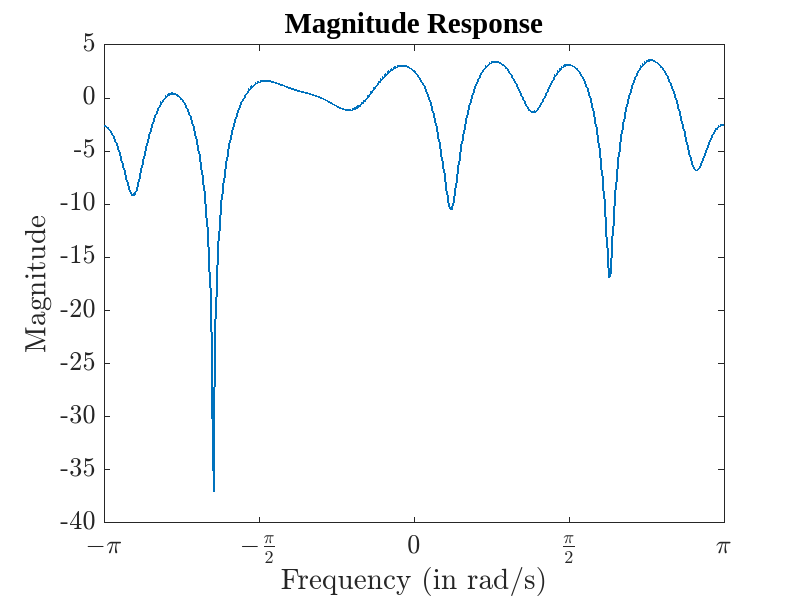

SNR   = 0:5:30;                        % Signal-to-noise ratio in dB
N_SNR = length(SNR);                   % Length of SNR

L = 10;                                % Channel's length in samples

h = randn(L,1) +1i*rand(L,1);
h = h/norm(h);

h_freq = fft(h,N_FFT);

figure;

set(gcf,'position',[0 0 800 600])

plot(freq,fftshift(20*log10(abs(h_freq))),'linewidth',linewidth,'markersize',markersize);

title('Magnitude Response','fontname',fontname,'fontsize',fontsize);
xlabel('Frequency (in rad/s)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('Magnitude','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

xticks([-pi -pi/2 0 pi/2 pi]);

xlim([-pi,pi]);

set(gca,'ticklabelinterpreter','latex', ...
    'xticklabel',{'$-\pi$','$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$','$\pi$'}, ...
    'fontname',fontname,'fontsize',fontsize);

# Communication System

BER = zeros(N_SNR,1);

## Transmitter

m_bit     = randi([0 1],B*N*N_BLK,1);

code      = convenc(m_bit,trellis);
code_itlv = randintrlv(code,state);

m_mod     = qammod(code_itlv,Q,'gray','InputType','bit');     % QPSK or 4-QAM modulation

% x = m_mod;
x = reshape(m_mod,N,N_BLK/R);
x = [x; zeros(L,N_BLK/R)];
x = reshape(x,[],1);

Px = norm(x)^2/length(x);                                      % Average transmission power

## Channel

z = fftfilt(h,x);                                              % Filter signal by channel

## Receiver

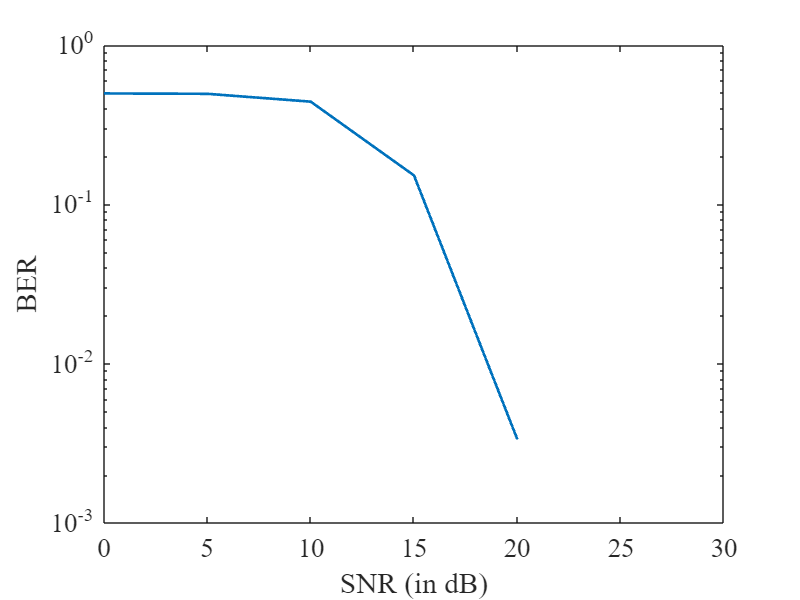

for snr_ind = 1:N_SNR    
    v  = (randn(length(z),1) + 1i*randn(length(z),1))/sqrt(2); % AWGN noise
    Pv = norm(v)^2/length(v);                                  % Average noise power
    
    v  = sqrt(((Px/Pv))*(10^(-SNR(snr_ind)/10)))*v;            % True AWGN noise
    
    y = z + v;                                                 % Received signal
    
    y = reshape(y,N+L,N_BLK/R);                                % Serial to parallel conversion
    y = y(1:N,:);

    H = toeplitz([h; zeros(N-L,1)],[h(1) zeros(1,N-1)]);

    m_mod_hat    = reshape(H\y,[],1);    
    m_hat    = qamdemod(m_mod_hat,Q,'gray','OutputType','bit');

    code_hat_deitrlv   = randdeintrlv(m_hat,state);
    
    m_bit_hat   = vitdec(code_hat_deitrlv,trellis,tblen,'trunc','hard');

    BER(snr_ind) = sum(sum(abs(m_bit(:)-m_bit_hat(:))))/length(m_bit_hat(:));   
end

figure;

set(gcf,'position',[0 0 800 600]);

semilogy(SNR,BER(:,1),'linewidth',linewidth);
% hold on;
% semilogy(SNR,BER(:,2),'linewidth',linewidth);
% semilogy(SNR,BER(:,3),'linewidth',linewidth);
% semilogy(SNR,BER(:,4),'linewidth',linewidth);
% semilogy(SNR,BER(:,5),'linewidth',linewidth);
% semilogy(SNR,BER(:,6),'linewidth',linewidth);

xlabel('SNR (in dB)','fontname',fontname,'fontsize',fontsize);
ylabel('BER','fontname',fontname,'fontsize',fontsize);

% legend({'BPSK','4-QAM','8-QAM','16-QAM','32-QAM','64-QAM'},'fontname',fontname,'fontsize',fontsize,'location','southwest')
% legend box off

xlim([0 30]);

set(gca,'fontname',fontname,'fontsize',fontsize);